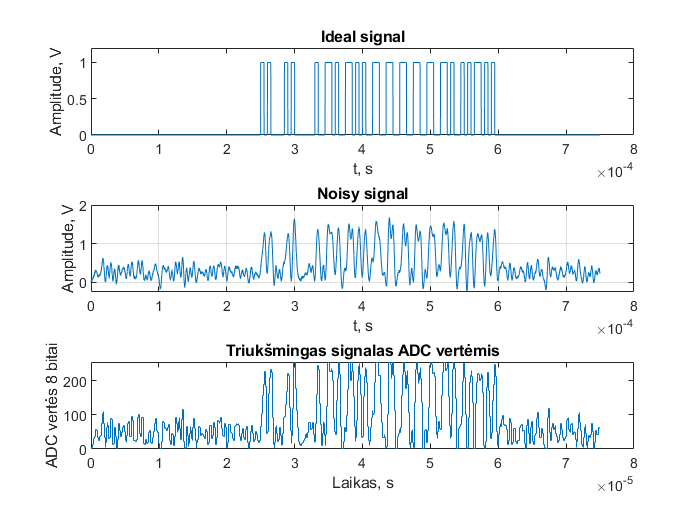

fdiskret = 10E6;
tdiskret = 1/fdiskret;

tprescaler = 10;

idealOne = [ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler))];
idealZero = [zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler))];

dataSend = "101101110101010101011000111";
[idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule, signalSNR] = GenerateSignal(dataSend, 1);

%{
[idealSignal2, noisySignal2, discretizedSignal2, ADCsignal2, ADCpreambule2] = GenerateSignal(dataSend, 1);

susceilintas = [zeros(1, 500), noisySignal2];
susceilintas = susceilintas(1:length(noisySignal));
suPersidengimuSignalas = noisySignal + susceilintas;
suPersidengimuSignalas = suPersidengimuSignalas(1:10:length(suPersidengimuSignalas));
%}
N = length(idealSignal);
n = 0:N-1;
t = 0:1/fdiskret:1/fdiskret*(N-1);

subplot(3, 1, 1)
plot(t, idealSignal)
xlabel('t, s')
ylabel('Amplitude, V')
title('Ideal signal')
ylim([0, 1.2])

subplot(3, 1, 2)
plot(t, noisySignal)
ylabel('Amplitude, V')
xlabel('t, s')
title('Noisy signal')
grid on

subplot(3, 1, 3)
N = length(ADCsignal);
n = 0:N-1;
t = 0:1/fdiskret:1/fdiskret*(N-1);
stairs(t, ADCsignal)
ylabel('ADC vertės 8 bitai')
xlabel('Laikas, s')
title('Triukšmingas signalas ADC vertėmis')
ylim([0, 255])

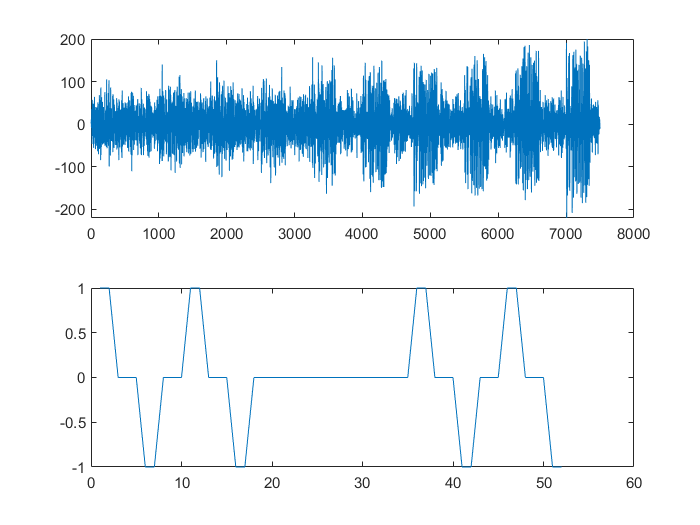

pastumimasN = 2;
idealPreambule = [zeros(1, 5), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(2E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, 10)];
pastumtaPreambule = [zeros(1, pastumimasN), idealPreambule(1:length(idealPreambule)-pastumimasN)];
diferencijuotaPreambule = idealPreambule - pastumtaPreambule;

pastumtas = [zeros(1, pastumimasN), ADCsignal(1:length(ADCsignal)-pastumimasN)];
diferencijuotasPilnas = ADCsignal - pastumtas;

diferencijuotaPreambule = diferencijuotaPreambule(6:57);
[idealSignal, noisySignal, discretizedSignal, ADCsignal2, ADCpreambule] = GenerateSignal(dataSend, 1);

ADCsignal2 = zeros(1, 10*750);
generuojama_amplitude_viso = 0.2:0.1:1.1;
for generuojama_amplitude_index = 1:10
    [idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, generuojama_amplitude_viso(generuojama_amplitude_index));
    ADCsignal2(750*(generuojama_amplitude_index-1)+1:750*(generuojama_amplitude_index-1)+750) = ADCsignal;
end

%ADCsignal2 = [ADCsignal2, zeros(1, 90)];

%ADCsignal2 = [zeros(1, 10), ADCsignal, zeros(1, 90), ADCsignal2, zeros(1, 20), ADCsignal3];
pastumtas = [zeros(1, pastumimasN), ADCsignal2(1:length(ADCsignal2)-pastumimasN)];
diferencijuotasPilnas = ADCsignal2 - pastumtas;

figure
subplot(2, 1, 1)
plot(diferencijuotasPilnas)
subplot(2, 1, 2)
plot(diferencijuotaPreambule)


dOneOne = [0, 0, 0, 0, -1, -1, 0, 0, 0, 1, 1, 0, 0, 0, -1, -1, 0, 0, 0, 0];
dOneZero = [0, 0, 0, 0, -1, -1, 0, 0, 0, 0, 0, 0, 0, 0, 1, 1, 0, 0, 0, 0];
dZeroOne = [0, 0, 0, 0, 1, 1, 0, 0, 0, 0, 0, 0, 0, 0, -1, -1, 0, 0, 0, 0];
dZeroZero = [0, 0, 0, 0, 1, 1, 0, 0, 0, -1, -1, 0, 0, 0, 1, 1, 0, 0, 0, 0];

y = GenerateConv(diferencijuotasPilnas, diferencijuotaPreambule); %diferencijuotas
yOneOne = GenerateConv(diferencijuotasPilnas, dOneOne); %diferencijuotas
yOneZero = GenerateConv(diferencijuotasPilnas, dOneZero); %diferencijuotas
yZeroOne = GenerateConv(diferencijuotasPilnas, dZeroOne); %diferencijuotas
yZeroZero = GenerateConv(diferencijuotasPilnas, dZeroZero); %diferencijuotas
%yy = GenerateConv(ADCsignal, idealPreambule); %diferencijuotas
idealPreambule = idealPreambule(6:55);
yn = GenerateConv(ADCsignal2, idealPreambule); %NEdiferencijuotas

[a, b] = max(y(1:300))

a = 561

b = 269

b = b - 1

b = 268

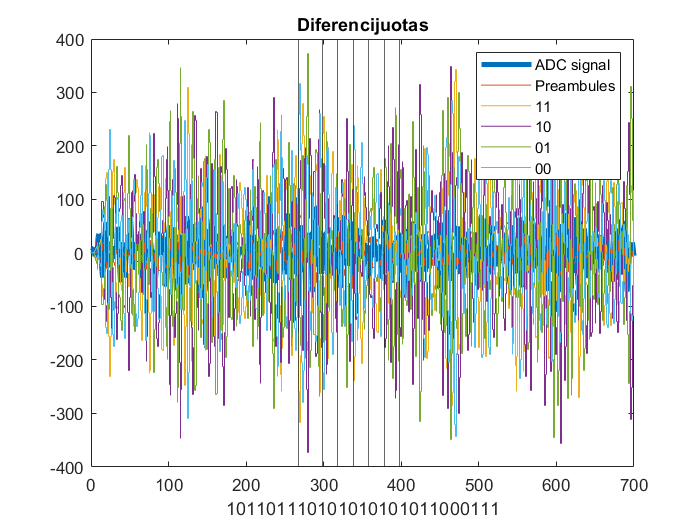

figure
plot(diferencijuotasPilnas, 'LineWidth',3)
hold on
stairs(y/8)
stairs(yOneOne)
stairs(yOneZero*1.5)
stairs(yZeroOne*1.5)
stairs(yZeroZero)
xline(b)
xline(b+30)
xline(b+30+20)
xline(b+30+20*2)
xline(b+30+20*3)
xline(b+30+20*4)
xline(b+30+20*5)
xlabel(dataSend)
xlim([0, 700])
title("Diferencijuotas")
legend("ADC signal", "Preambules", "11", "10", "01", "00")
hold off

iOne = idealOne(1:10:length(idealOne));
iZero = idealZero(1:10:length(idealZero));

iZeroZero = [iZero, iZero];
iZeroOne = [iZero, iOne];
iOneZero = [iOne, iZero];
iOneOne = [iOne, iOne];

yi = GenerateConv(ADCsignal2, idealPreambule); %diferencijuotas
iOneOne = GenerateConv(ADCsignal2, iOneOne); %diferencijuotas
iOneZero = GenerateConv(ADCsignal2, iOneZero); %diferencijuotas
iZeroOne = GenerateConv(ADCsignal2, iZeroOne); %diferencijuotas
iZeroZero = GenerateConv(ADCsignal2, iZeroZero); %diferencijuotas

[a, b] = max(y(1:300))

a = 561

b = 269

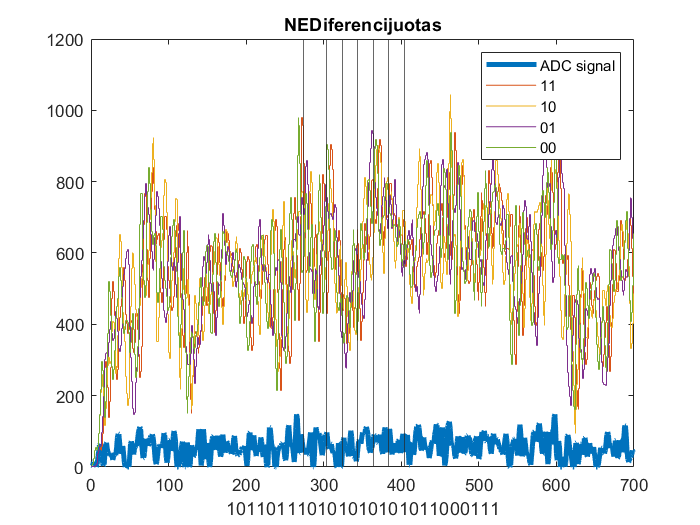

b = b + 5;

figure
plot(ADCsignal2, 'LineWidth',3)
hold on
stairs(iOneOne)
stairs(iOneZero)
stairs(iZeroOne)
stairs(iZeroZero)
xline(b)
xline(b+30)
xline(b+30+20)
xline(b+30+20*2)
xline(b+30+20*3)
xline(b+30+20*4)
xline(b+30+20*5)
xlabel(dataSend)
xlim([0, 700])
title("NEDiferencijuotas")
legend("ADC signal", "11", "10", "01", "00")
hold off



max1 = zeros(1, 50);
max2 = zeros(1, 50);
eng1 = zeros(1, length(y));
eng2 = zeros(1, 50);

diferencijuotasPilnas_ma5 = GenerateMA(diferencijuotasPilnas, 5);
diferencijuotaPreambule_ma5 = GenerateMA(diferencijuotaPreambule, 5);
diferencijuotasPilnas_ma10 = GenerateMA(diferencijuotasPilnas, 10);
diferencijuotaPreambule_ma10 = GenerateMA(diferencijuotaPreambule, 10);
yd_ma5 = GenerateConv(diferencijuotasPilnas_ma5, diferencijuotaPreambule_ma5); %Diferencijuotas
yd_ma10 = GenerateConv(diferencijuotasPilnas_ma10, diferencijuotaPreambule_ma10); %Diferencijuotas

for i = 50:length(y)
     %[maksimumai, indeksai] = maxk(y(i:i+50),3);
     %max1 = [max1, maksimumai(1)];
     %max2 = [max2, maksimumai(3)];
     eng1(i) = sum(abs(ADCsignal2(i-50+1:i) .* ADCsignal2(i-50+1:i)))/50;

     %eng2 = [eng2, sum(abs(ADCsignal2_ma(i:i+50) .* ADCsignal2_ma(i:i+50)))/50];
end

%{
max11 = zeros(1, length(y));
max22 = zeros(1, 49);
for i = 1:length(y)-50
     [pks, locs] = findpeaks(y(i:i+50));
     [maksimumai, indeksai] = maxk(pks,2);
     if(length(maksimumai) >= 1)
        max11(i) =maksimumai(1);
     else
         ax11 = [max11, 0];
     end
     
     %max22 = [max22, maksimumai(2)];
end
%}

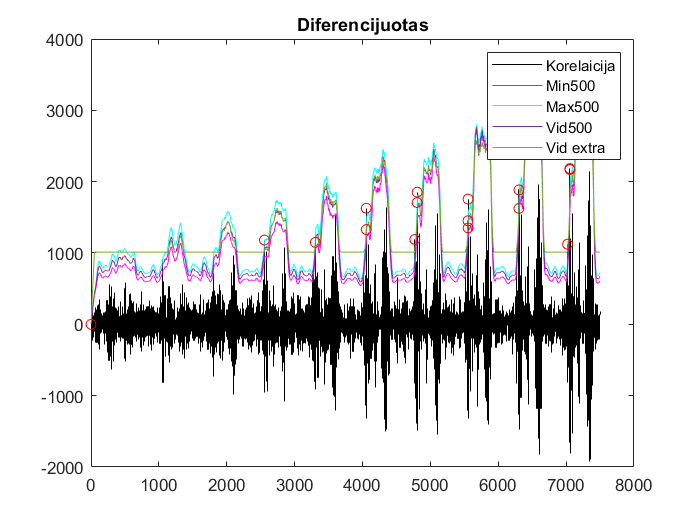

aproksimacija = zeros(1, length(eng1));
approx1 = zeros(1, length(eng1));
approx2 = zeros(1, length(eng1));
approx3 = zeros(1, length(eng1));
approx4 = zeros(1, length(eng1));
approx5 = zeros(1, length(eng1));
approx6 = zeros(1, length(eng1));
approx7 = zeros(1, length(eng1));

approx4n = zeros(1, length(eng1));
approx5n = zeros(1, length(eng1));
approx6n = zeros(1, length(eng1));
approx7n = zeros(1, length(eng1));

approxp1ma = zeros(1, length(eng1));
approxp2ma = zeros(1, length(eng1));

p1 = [-2.59019897376239e-06,	0.175415774775950,	-81.1481740485828]; %vidurkio
p2 = [-2.02753473199491e-06,	0.164646049460140,	-181.191767498869]; %Min kvantiliai 0.25
p3 = [-3.43562096965570e-06,	0.196276692528014,	-64.3807161268730]; %Max kvantiliai 0.75
p4 = [1.26652563463124e-06,	0.0716142859516929,	420.711120132271]; %min su 500
p5 = [-7.06427462946576e-07,	0.119198055033279,	434.307610667475]; %max su 500
p6 = [2.20077454415045e-07,	0.0960471709979493,	432.355923902787]; %vidurkis su 500

p4n = [-1.18468444565475e-06,	0.206298228589546,	959.123190169913]; %min1000
p5n = [-3.57140346192127e-06,	0.258990119288600,	980.898042488115]; %max 1000
p6n = [-2.39409932854372e-06,	0.232842248034768,	968.285931306435]; %vid 1000
p7n = [1.62735789189586e-06,	0.120910302747956,	1677.11606707998]; %naujas vid be 1000
p7n = p6n;

%p1ma = [-1.31146316643672e-06,	0.0787947675230736,	-42.7227689298363];
p1ma = [-1.31146316643672e-06,	0.0787947675230736,	-100.7227689298363]; %5ma
p2ma = [-1.50934830330594e-07,	0.0104483772788822,	-3.57135517562399]; %10ma

for i = 1:length(eng1)
     approx1(i) = eng1(i)^2*p1(1)+eng1(i)*p1(2)+p1(3);
     approx2(i) = eng1(i)^2*p2(1)+eng1(i)*p2(2)+p2(3);
     approx3(i) = eng1(i)^2*p3(1)+eng1(i)*p3(2)+p3(3);
     approx4(i) = eng1(i)^2*p4(1)+eng1(i)*p4(2)+p4(3);
     approx5(i) = eng1(i)^2*p5(1)+eng1(i)*p5(2)+p5(3);
     approx6(i) = eng1(i)^2*p6(1)+eng1(i)*p6(2)+p6(3);

     if(eng1(i) >= 6835.83086078639)
        approx7(i) = eng1(i)^2*p1(1)+eng1(i)*p1(2)+p1(3);
     else
        approx7(i) = 1012.31987247609;
     end

     approx4n(i) = eng1(i)^2*p4n(1)+eng1(i)*p4n(2)+p4n(3);
     approx5n(i) = eng1(i)^2*p5n(1)+eng1(i)*p5n(2)+p5n(3);
     approx6n(i) = eng1(i)^2*p6n(1)+eng1(i)*p6n(2)+p6n(3);

     if(eng1(i) >= 6570)
         approxp1ma(i) = eng1(i)^2*p1ma(1)+eng1(i)*p1ma(2)+p1ma(3);
     else
         approxp1ma(i) = 433;
     end

     if(eng1(i) >= 6733)
         approxp2ma(i) = eng1(i)^2*p2ma(1)+eng1(i)*p2ma(2)+p2ma(3);
     else
         approxp2ma(i) = 59.98;
     end
     

     if(eng1(i) >= 6889.67755755754)
        approx7n(i) = eng1(i)^2*p7n(1)+eng1(i)*p7n(2)+p7n(3);
     else
        approx7n(i) = 2583.55055055055;
     end
end

load Apkirpta_ideali_preambule_d.mat %yy-ideali diferencijuota preambule
yyy = GenerateConv(y, yy); %du kartus koreliuotas 

suKirtimais = GenerateMA(approx7, 50);
kirtimaiX = zeros(1, length(suKirtimais));
kirtimaiY = zeros(1, length(suKirtimais));

for i = 1:length(suKirtimais)
    if(y(i) >= suKirtimais(i))
        kirtimaiX(i) = i;
        kirtimaiY(i) = y(i);
    end
end


figure
stairs(y, 'black')
hold on
plot(GenerateMA(approx4, 50), 'magenta')
plot(GenerateMA(approx5, 50), 'cyan')
plot(GenerateMA(approx6, 50))
plot(GenerateMA(approx7, 50))
scatter(kirtimaiX, kirtimaiY, 'red', 'o')
legend("Korelaicija", "Min500", "Max500", "Vid500", "Vid extra")
title("Diferencijuotas")
hold off

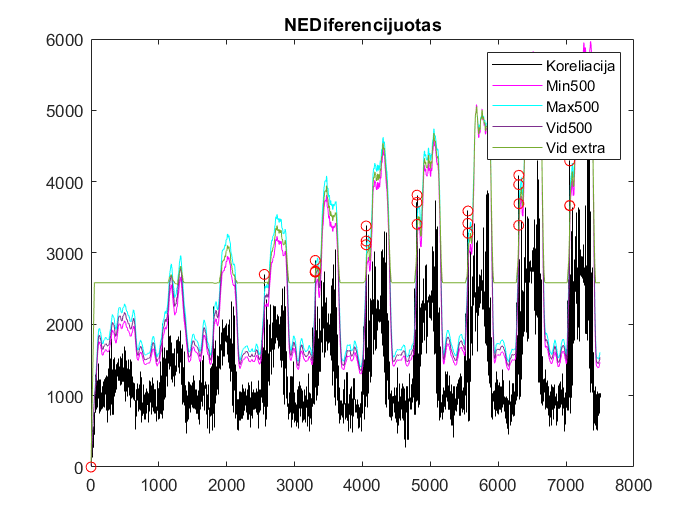

vidurkinimas = 50;

suKirtimais = GenerateMA(approx7n, vidurkinimas);
kirtimaiX = zeros(1, length(suKirtimais));
kirtimaiY = zeros(1, length(suKirtimais));

for i = 1:length(suKirtimais)
    if(yn(i) >= suKirtimais(i))
        kirtimaiX(i) = i;
        kirtimaiY(i) = yn(i);
    end
end

figure
stairs(yn, 'black')
hold on
plot(GenerateMA(approx4n, vidurkinimas), 'magenta') %Min
plot(GenerateMA(approx5n, vidurkinimas), 'cyan') %Max
plot(GenerateMA(approx6n, vidurkinimas)) %vid
plot(GenerateMA(approx7n, vidurkinimas)) %vid
scatter(kirtimaiX, kirtimaiY, 'red', 'o')
legend("Koreliacija", "Min500", "Max500", "Vid500", "Vid extra")
title("NEDiferencijuotas")
hold off

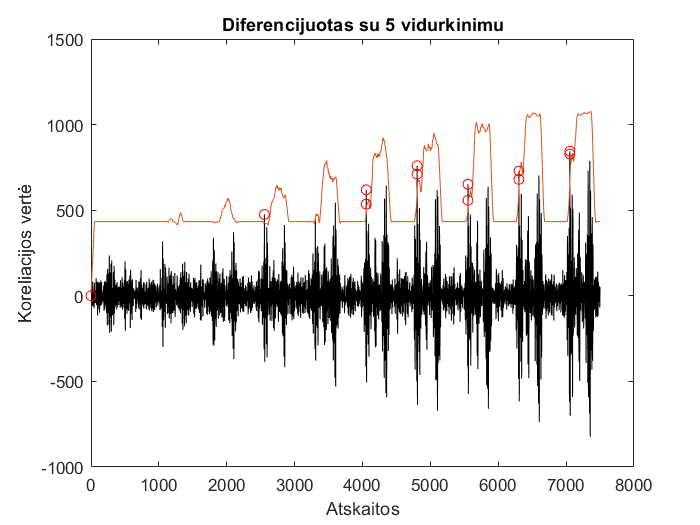

suKirtimais = GenerateMA(approxp1ma, vidurkinimas);
kirtimaiX = zeros(1, length(suKirtimais));
kirtimaiY = zeros(1, length(suKirtimais));

for i = 1:length(suKirtimais)
    if(yd_ma5(i) >= suKirtimais(i))
        kirtimaiX(i) = i;
        kirtimaiY(i) = yd_ma5(i);
    end
end


figure
plot(yd_ma5, "black")
hold on
plot(GenerateMA(approxp1ma, vidurkinimas))
scatter(kirtimaiX, kirtimaiY, 'red', 'o')
title("Diferencijuotas su 5 vidurkinimu")
xlabel("Atskaitos")
ylabel("Koreliacijos vertė")
hold off

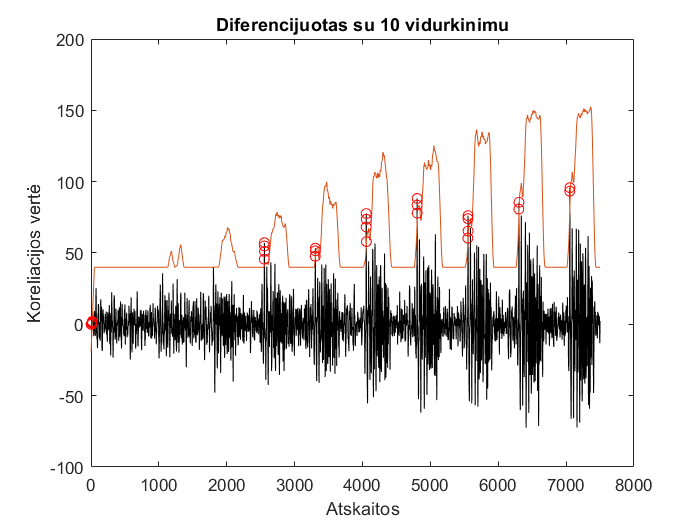

suKirtimais = GenerateMA(approxp2ma, 50)-20;
kirtimaiX = zeros(1, length(suKirtimais));
kirtimaiY = zeros(1, length(suKirtimais));

for i = 1:length(suKirtimais)
    if(yd_ma10(i) >= suKirtimais(i))
        kirtimaiX(i) = i;
        kirtimaiY(i) = yd_ma10(i);
    end
end


figure
plot(yd_ma10, "black")
hold on
plot(GenerateMA(approxp2ma, 50)-20)
scatter(kirtimaiX, kirtimaiY, 'red', 'o')
title("Diferencijuotas su 10 vidurkinimu")
xlabel("Atskaitos")
ylabel("Koreliacijos vertė")
hold off

SignaluKonvoliucija(ADCsignal, ADCpreambule, 1);

pastumimasN = 2
ADCsignal = ADCsignal;%suPersidengimuSignalas;

fdiskret = 10E6;
tdiskret = 1/fdiskret;
tprescaler = 1;
idealPreambule = [zeros(1, 5), ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(2E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, 10)];
pastumtaPreambule = [zeros(1, pastumimasN), idealPreambule(1:length(idealPreambule)-pastumimasN)];
diferencijuotaPreambule = idealPreambule - pastumtaPreambule;
ADCsignal2 = [zeros(1, 10), ADCsignal];
pastumtas = [zeros(1, pastumimasN), ADCsignal2(1:length(ADCsignal2)-pastumimasN)];
diferencijuotasPilnas = ADCsignal2 - pastumtas;
y = GenerateConv(diferencijuotasPilnas, diferencijuotaPreambule);

plot(y)
hold on
hold off
[a, b] = max(y)

iOne = [idealOne(1:10:length(idealOne)), zeros(1, pastumimasN*2)];
iZero = [idealZero(1:10:length(idealZero)), zeros(1, pastumimasN*2)];

pOne = [zeros(1, pastumimasN), iOne(1:length(iOne))];
pZero = [zeros(1, pastumimasN), iZero(1:length(iZero))];

pOne = pOne(1:length(iOne));
pZero = pZero(1:length(iZero));

dOne = iOne - pOne;
dZero = iZero - pZero;

dOne = dOne(1:10);
dZero = dZero(1:10);

iOne = idealOne(1:10:length(idealOne));
iZero = idealZero(1:10:length(idealZero));

iZeroZero = [iZero, iZero];
iZeroOne = [iZero, iOne];
iOneZero = [iOne, iZero];
iOneOne = [iOne, iOne];


dOneOne =  [0, 0, 0, 0, 0,-1, 0, 0, 0, 0, 1, 0, 0, 0, 0,-1, 0, 0, 0, 0];
dOneZero = [0, 0, 0, 0, 0,-1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 0, 0, 0];
dZeroOne = [0, 0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0,-1, 0, 0, 0, 0];
dZeroZero =[0, 0, 0, 0, 0, 1, 0, 0, 0, 0,-1, 0, 0, 0, 0, 1, 0, 0, 0, 0];

dOne = [0, 0, 0, 0, 0, -1, -1, 0, 0, 0];
dZero = [0, 0, 0, 0, 0, 1, 1, 0, 0, 0];
cdOne = GenerateConv(diferencijuotasPilnas, dOne);
cdZero = GenerateConv(diferencijuotasPilnas, dZero);
cOne = GenerateConv(ADCsignal, iOne);
cZero = GenerateConv(ADCsignal, iZero);

cdOneOne = GenerateConv(diferencijuotasPilnas, dOneOne);
cdZeroOne = GenerateConv(diferencijuotasPilnas, dZeroOne);
cdOneZero = GenerateConv(diferencijuotasPilnas, dOneZero);
cdZeroZero = GenerateConv(diferencijuotasPilnas, dZeroZero);

cZeroZero = GenerateConv(ADCsignal, iZeroZero);
cZeroOne = GenerateConv(ADCsignal, iZeroOne);
cOneZero = GenerateConv(ADCsignal, iOneZero);
cOneOne = GenerateConv(ADCsignal, iOneOne);

velinimasPreambules = 73;
plot(ADCsignal)
hold on
stairs(cdOne)
stairs(cdZero)
stairs([zeros(1, 10), cOne])
stairs([zeros(1, 10), cZero])

xline((velinimasPreambules));
xline((velinimasPreambules+30));
xline((velinimasPreambules+30+10));
xline((velinimasPreambules+30+20));
xline((velinimasPreambules+30+30));
xline((velinimasPreambules+30+40));

legend("Signal", "one", "zero", "old one", "old zero")

hold off
plot(ADCsignal)
hold on
stairs(cdOneOne)
stairs(cdZeroOne)
stairs(cdOneZero)
stairs(cdZeroZero)

stairs([zeros(1, 10), cOneOne])
stairs([zeros(1, 10), cZeroOne])
stairs([zeros(1, 10), cOneZero])
stairs([zeros(1, 10), cZeroZero])

xline((velinimasPreambules));
xline((velinimasPreambules+30));
xline((velinimasPreambules+30+10));
xline((velinimasPreambules+30+30));
xline((velinimasPreambules+30+50));
xline((velinimasPreambules+30+70));

legend("Signal", "one one", "zero one", "one zero", "zero zero", "old 11", "old 01", "old 10", "old 00")

hold off
SignaluKonvoliucija(ADCsignal, ADCpreambule, 1);

%NEdiferencijuotas
fdiskret = 10E6;
tdiskret = 1/fdiskret;

tprescaler = 10;

idealOne = [ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler))];
idealZero = [zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler))];

iOne = idealOne(1:10:length(idealOne));
iZero = idealZero(1:10:length(idealZero));

iZeroZero = [iZero, iZero];
iZeroOne = [iZero, iOne];
iOneZero = [iOne, iZero];
iOneOne = [iOne, iOne];

dataSend = "101101110101010101011000111";
pastumimasN = 2;

idealPreambule = [zeros(1, 5), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(2E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, 10)];
idealPreambule = idealPreambule(6:55);

gauta_geru = 0;
blogi = [0, 0, 0, 0];
for yy = 1:100
    
    [idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, 0.5);
    [idealSignal2, noisySignal2, discretizedSignal2, ADCsignal2, ADCpreambule2] = GenerateSignal(dataSend, 1);
    [idealSignal3, noisySignal3, discretizedSignal3, ADCsignal3, ADCpreambule3] = GenerateSignal(dataSend, 1.4);
                
    ADCsignal2 = [zeros(1, 10), ADCsignal, zeros(1, 90), ADCsignal2, zeros(1, 20), ADCsignal3];

    y = GenerateConv(ADCsignal2, idealPreambule);
    yOneOne = GenerateConv(ADCsignal2, iOneOne);
    yOneZero = GenerateConv(ADCsignal2, iOneZero);
    yZeroOne = GenerateConv(ADCsignal2, iZeroOne);
    yZeroZero = GenerateConv(ADCsignal2, iZeroZero);
    koreliacijos_reiksmes = [yOneOne; yOneZero; yZeroOne; yZeroZero];

    [a, b] = max(y(1:300));
    gauta_seka = "";
    geras = 1;
    for i = 1:4
        [~, max_index] = max(koreliacijos_reiksmes(:, b + 30 + 20 * i));
        switch max_index
            case 1
                gauta_seka = append(gauta_seka,"11");
                gauta_seka = "11";
            case 2 
                gauta_seka = append(gauta_seka,"10");
                gauta_seka = "10";
            case 3 
                gauta_seka = append(gauta_seka,"01");
                gauta_seka = "01";
            case 4
                gauta_seka = append(gauta_seka,"00");
                gauta_seka = "00";
        end
        if(not(gauta_seka == dataSend{1}(i*2-1:i*2)))
            geras = 0;
            blogi(i) = blogi(i) + 1;
        end
    end
    if(geras == 1)
        gauta_geru = gauta_geru + 1;
    end
end
gauta_geru

%Diferencijuotas
fdiskret = 10E6;
tdiskret = 1/fdiskret;

tprescaler = 10;

idealOne = [ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler))];
idealZero = [zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler))];

dataSend = "101101110101010101011000111";
pastumimasN = 2;

idealPreambule = [zeros(1, 5), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(2E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, 10)];
pastumtaPreambule = [zeros(1, pastumimasN), idealPreambule(1:length(idealPreambule)-pastumimasN)];
diferencijuotaPreambule = idealPreambule - pastumtaPreambule;
diferencijuotaPreambule = diferencijuotaPreambule(6:57);
dOneOne = [0, 0, 0, 0, -1, -1, 0, 0, 0, 1, 1, 0, 0, 0, -1, -1, 0, 0, 0, 0];
dOneZero = [0, 0, 0, 0, -1, -1, 0, 0, 0, 0, 0, 0, 0, 0, 1, 1, 0, 0, 0, 0];
dZeroOne = [0, 0, 0, 0, 1, 1, 0, 0, 0, 0, 0, 0, 0, 0, -1, -1, 0, 0, 0, 0];
dZeroZero = [0, 0, 0, 0, 1, 1, 0, 0, 0, -1, -1, 0, 0, 0, 1, 1, 0, 0, 0, 0];

viso_geru = [];
blogi = [0, 0, 0, 0];
for k = 1:0.1:3
    gauta_geru = 0;
    for yy = 1:100
        
        [idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, 0.5);
        [idealSignal2, noisySignal2, discretizedSignal2, ADCsignal2, ADCpreambule2] = GenerateSignal(dataSend, 1);
        [idealSignal3, noisySignal3, discretizedSignal3, ADCsignal3, ADCpreambule3] = GenerateSignal(dataSend, 1.4);
                    
        ADCsignal2 = [zeros(1, 10), ADCsignal, zeros(1, 90), ADCsignal2, zeros(1, 20), ADCsignal3];
        pastumtas = [zeros(1, pastumimasN), ADCsignal2(1:length(ADCsignal2)-pastumimasN)];
        diferencijuotasPilnas = ADCsignal2 - pastumtas;
        y = GenerateConv(diferencijuotasPilnas, diferencijuotaPreambule); %diferencijuotas
        yOneOne = GenerateConv(diferencijuotasPilnas, dOneOne); %diferencijuotas
        yOneZero = GenerateConv(diferencijuotasPilnas, dOneZero); %diferencijuotas
        yZeroOne = GenerateConv(diferencijuotasPilnas, dZeroOne); %diferencijuotas
        yZeroZero = GenerateConv(diferencijuotasPilnas, dZeroZero); %diferencijuotas
        koreliacijos_reiksmes = [yOneOne; yOneZero*k; yZeroOne*k; yZeroZero];
    
        [a, b] = max(y(1:300));
        b = b;
        gauta_seka = "";
        geras = 1;
        for i = 1:4
            [~, max_index] = max(koreliacijos_reiksmes(:, b + 30 + 20 * i));
            switch max_index
                case 1
                    gauta_seka = append(gauta_seka,"11");
                    gauta_seka = "11";
                case 2 
                    gauta_seka = append(gauta_seka,"10");
                    gauta_seka = "10";
                case 3 
                    gauta_seka = append(gauta_seka,"01");
                    gauta_seka = "01";
                case 4
                    gauta_seka = append(gauta_seka,"00");
                    gauta_seka = "00";
            end
            if(not(gauta_seka == dataSend{1}(i*2-1:i*2)))
                geras = 0;
                blogi(i) = blogi(i) + 1;
            end
        end
        if(geras == 1)
            gauta_geru = gauta_geru + 1;
        end
    
        %if(gauta_seka == dataSend{1}(1:8))
        %    gauta_geru = gauta_geru + 1;
        %end
    end
    viso_geru = [viso_geru, gauta_geru];
end
figure
plot(viso_geru)
ylabel("Teisingu skaicius is 1000")
xlabel("k, dauginimo koeficientas")